close all;
clc;

## User Input

modelName = 'HRTIM_main';

% Simulation time in seconds
sim_time_sec = 120e-6;

% Opens the simulink sim graphically if true
open_sim = true;


## Load Variables

% Load sim variables
HRTIM_simulink_var;

out_params = 6×3 table
             Parameter              Value    Unit 
    ____________________________    _____    _____

    "Primary resonant frequency"     264     "kHz"
    "Max tracked freq"               277     "kHz"
    "Min tracked freq"               198     "kHz"
    "Lead time"                        5     "ns" 
    "PRF frequency"                  200     "Hz" 
    "PRF DC"                           1     "%"  


## Run Sim

% Open model graphically
if open_sim == true
    open_system(modelName); 
end

% Create the SimulationInput object
simIn = Simulink.SimulationInput(modelName);

% Specify the StartTime and StopTime (values must be passed as strings)
simIn = setModelParameter(simIn, 'StartTime', '0', 'StopTime', string(sim_time_sec));

% Run the simulation
simOut = sim(simIn);


## Process Results

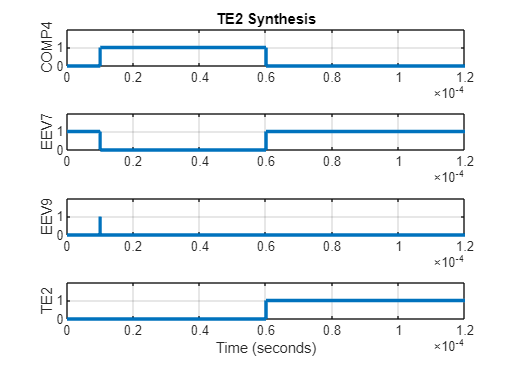

plot_te2_synth;

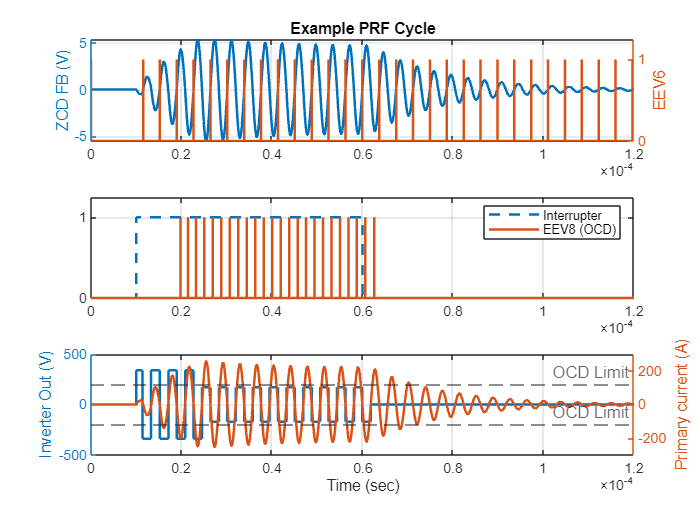

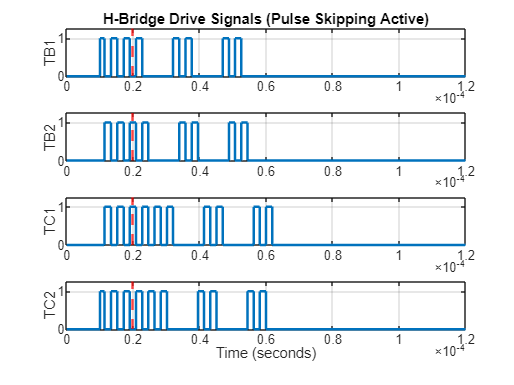

plot_inverter_waveform;